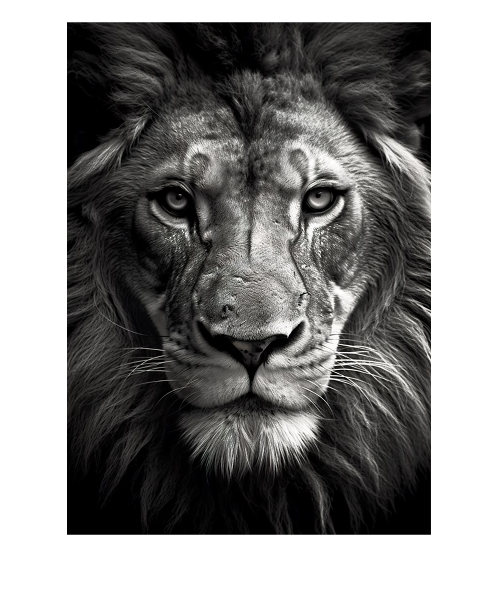

bild = imread('1.jpg');
imshow(bild);

b = switchPicParts(bild);

zahl_Zeilen = 0

zahl_Spalten = 0

zahl_Zeilen = 1

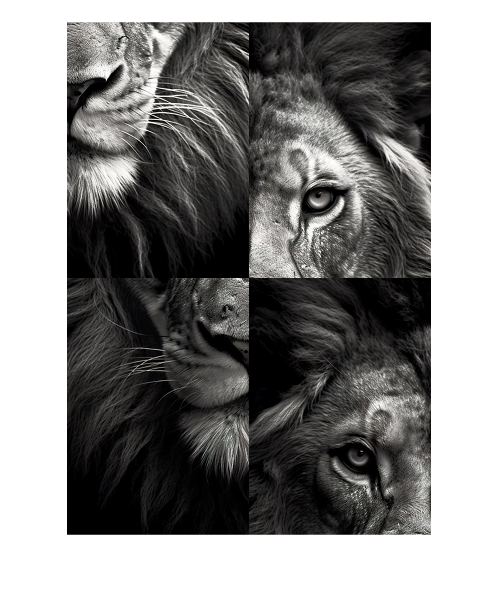

figure;
imshow(b);


figure;
b2 = switchPicPartsDiagonalen(bild);

zahl_Zeilen = 0

zahl_Spalten = 0

zahl_Zeilen = 1

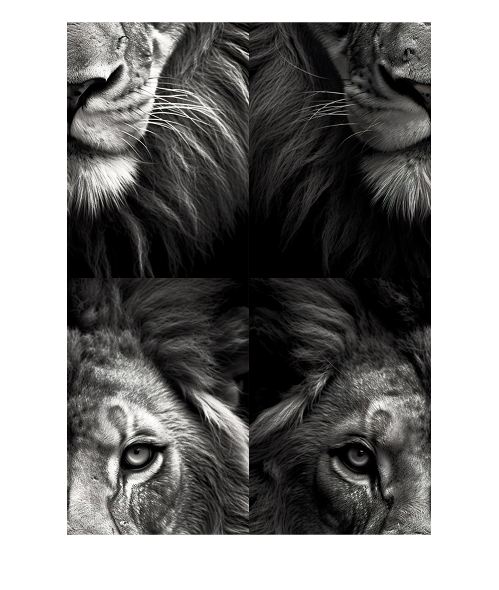

imshow(b2);

function [b] = switchPicParts(bild)
    b = bild;
    z = size(bild, 1);
    s = size(bild, 2);

    mitte_z = round(z/2);
    mitte_s = round(s/2);

    zahl_Zeilen = 0
    zahl_Spalten = 0
    if mod(z,2) == 0
        zahl_Zeilen = 1
    end
    if mod(s,2) == 0
        zahl_Spalten = 1
    end
    b(1:mitte_z,1:mitte_s,:) = bild(mitte_z+zahl_Zeilen:z,mitte_s+zahl_Spalten:s,:);
    b(mitte_z+zahl_Zeilen:z,mitte_s+zahl_Spalten:s,:) = bild(1:mitte_z,1:mitte_s,:);
end

function [b] = switchPicPartsDiagonalen(bild)
    b = bild;
    z = size(bild, 1);
    s = size(bild, 2);

    mitte_z = round(z/2);
    mitte_s = round(s/2);

    zahl_Zeilen = 0
    zahl_Spalten = 0
    if mod(z,2) == 0
        zahl_Zeilen = 1
    end
    if mod(s,2) == 0
        zahl_Spalten = 1
    end
    b(1:mitte_z,1:mitte_s,:) = bild(mitte_z+zahl_Zeilen:z,mitte_s+zahl_Spalten:s,:);
    b(mitte_z+zahl_Zeilen:z,mitte_s+zahl_Spalten:s,:) = bild(1:mitte_z,1:mitte_s,:);

    b(mitte_z+zahl_Zeilen:z, 1:mitte_s,:) = bild(1:mitte_z, mitte_s+zahl_Spalten:s,:);
    b(1:mitte_z,mitte_s+zahl_Spalten:s,:) = bild(mitte_z+zahl_Zeilen:z, 1:mitte_s,:);
end